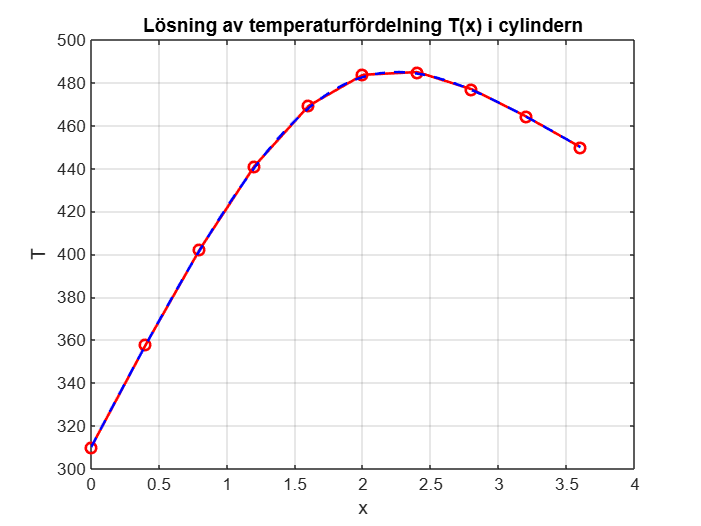

clear all, close all, clf

function [xi,Ti] = FDM(N)
    L=3.6;
    
    
    h= L/(N+1);
    x=linspace(0,L,N+2);%x-värden
    %Randvärden
    T0=310;
    TL=450;
    
    %Funktioner
    k=@(x) 3+x/7;%
    Q=@(x) 280*exp(-(x-L/2)^2);
    
    %Skapa matriser
    A=zeros(N,N);
    b=zeros(N,1);
    
    for j=2:N+1
    
        xj=x(j);
        kj=k(xj);
        Qj=Q(xj);
    
        %Matriselement
        a1j = 1/h^2-1/(2*h*7*kj);
        a2j = -2/h^2;
        a3j = 1/h^2 + 1/(2*h*7*kj);
    
        % insättning i A
        if j>2
            A(j-1,j-2) = a1j;
        end
        A(j-1,j-1) = a2j;
        if j<N+1
            A(j-1,j) = a3j;
        end
        b(j-1) = -Qj/kj;
    
    end
    
    %sätter in randvillkor i b
    b(1) = b(1)-T0*(1/h^2-1/(2*h*7*k(x(2))));
    b(end) = b(end) -TL*(1/h^2 + 1/(2*h*7*k(x(end-1))));
    %värden på T mellan Randvärden
    T_mellan= A\b;
    
    %Sätter in Randvärden i T
    T=[T0;T_mellan;TL];
    Ti=T;
    xi=x;
end

N=8;%antal inre punkter
%Lösningar:
x_intr = 1.65;
[x,T] = FDM(N);
[x1,T1] = FDM(2*N);
[x2,T2] = FDM(4*N);
[x3,T3] = FDM(8*N);
[x4,T4] = FDM(16*N);
[x5,T5] = FDM(32*N);
[x6,T6] = FDM(64*N);

T_value1 = FindTofX(x,T,x_intr);
T_value2 = FindTofX(x1,T1,x_intr);
T_value3 = FindTofX(x2,T2,x_intr);
T_value4 = FindTofX(x3,T3,x_intr);
T_value5 = FindTofX(x4,T4,x_intr);
T_value6 = FindTofX(x5,T5,x_intr);
T_value7 = FindTofX(x6,T6,x_intr);
function T_val = FindTofX(xx,TT,xinterior)
    [~,intre1] = min(abs(xx-xinterior));
    %interpolera kring 3 punkter
    T_val1 = interp1(xx(intre1-1:1:intre1+1),TT(intre1-1:1:intre1+1),xinterior,'pchip');
    T_val = T_val1;

end
%----undersökning
%hitta punker att interpolera
%[~,intre1] = min(abs(x-x_intr));%x=1.65
%fprintf('Xindex=%.4f\n',intre1);
%fprintf('j=%d x(j)=%.4f\n',intre1,x(intre1));
%fprintf('j=%d x(j)=%.4f\n',intre1+1,x(intre1+1));
%x(intre1-1:1:intre1+1)
%-----Ej för denna uppgift-----
%[~,intre2] = min(abs(x-2.96));%x=2.96
%fprintf('Xindex=%.4f\n',intre2);
%fprintf('j=%d x(j)=%.4f\n',intre2,x(intre2));
%fprintf('j=%d x(j)=%.4f\n',intre2+1,x(intre2+1));
%-------------------------------

%T_value1 = interp1(x(intre1-1:1:intre1+1),T(intre1-1:1:intre1+1),x_intr,'pchip');

%T_value2 = interp1(x,T(:),2.96,'linear');
%Plotta
plot(x,T,'o-r','LineWidth',1.5);
hold on
plot(x6,T6,'--b','LineWidth',1.5)
xlabel('x');
ylabel('T');
title('Lösning av temperaturfördelning T(x) i cylindern')
grid on;

fprintf('T(1.65)=%.4f\n',T_value1);

T(1.65)=471.6161


fprintf('T(1.65)=%.4f\n',T_value2);

T(1.65)=471.1174


fprintf('T(1.65)=%.4f\n',T_value3);

T(1.65)=470.8323


fprintf('T(1.65)=%.4f\n',T_value4);

T(1.65)=470.7787


fprintf('T(1.65)=%.4f\n',T_value5);

T(1.65)=470.7622


fprintf('T(1.65)=%.4f\n',T_value6);

T(1.65)=470.7583


fprintf('T(1.65)=%.4f\n',T_value7);

T(1.65)=470.7573


fprintf('T(max)=%.4f\n',max(T));

T(max)=485.0309


%fprintf('T(2.96)=%.4f\n',T_value2);



